# Name - Aman Kumar

# Roll No - 200123007

# **LAB ASSIGNMENT 09**

## **Crank Nicolson**

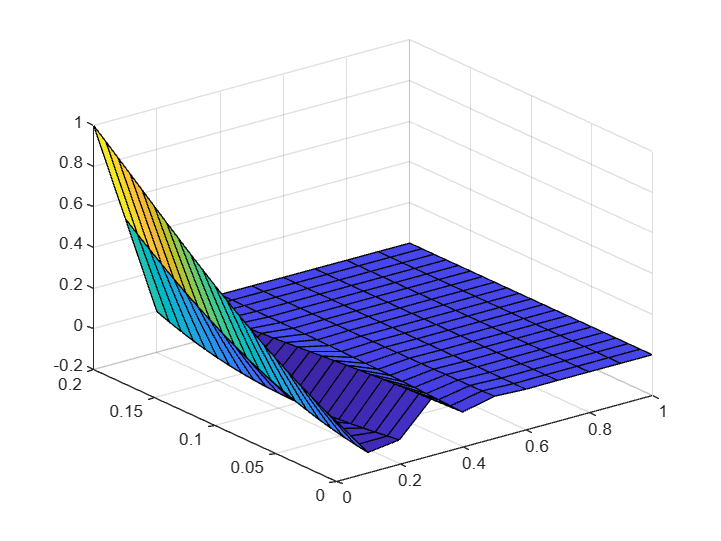

calculateOptionPrice(0.5);

## FTCS

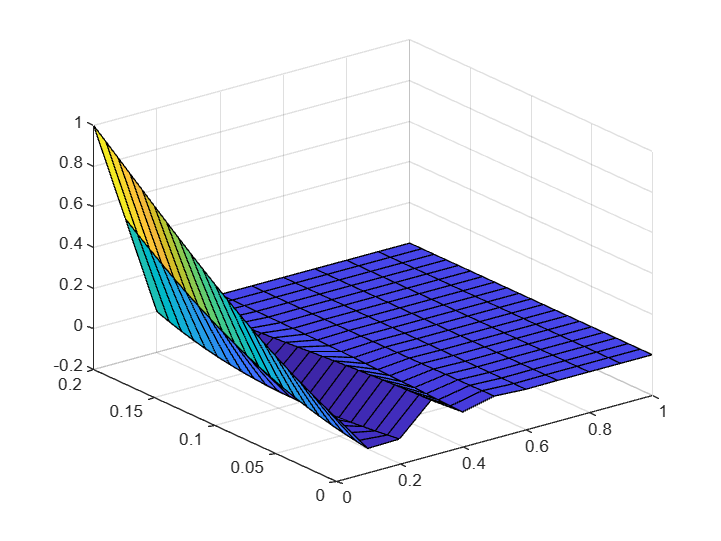

figure(2);
calculateOptionPrice(0);

## BTCS

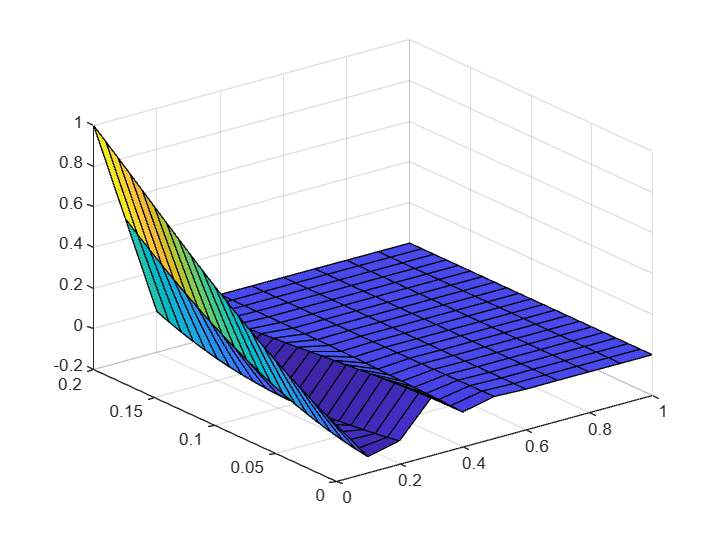

figure(3);
calculateOptionPrice(1);

function optionPrice = calculateOptionPrice(method)
    % Parameter Initialization
    spaceStep = 0.1;
    timeStep = 0.01;
    maturityTime = 0.2;
    % strikePrice = 100;     % Not used
    volatility = 0.25;
    interestRate = 0.05;
    maxRate = 1;

    % Discretized Time and Space
    timeGrid = 0:timeStep:maturityTime;
    rateGrid = 0:spaceStep:maxRate;
    numOfRateSteps = length(rateGrid);
    numOfTimeSteps = length(timeGrid);

    % Coefficient Functions
    alphaFunc = @(x) volatility^2 * x^2 / (2 * spaceStep^2);
    betaFunc = @(x) (1 - interestRate * x) / (2 * spaceStep);

    % Initialize Matrices for Crank-Nicolson method
    matrixA = eye(numOfRateSteps, numOfRateSteps);
    matrixB = eye(numOfRateSteps, numOfRateSteps);

    % Populate matrixA and matrixB
    for i = 2:numOfRateSteps-1
        matrixA(i, i) = 1/timeStep - 2 * alphaFunc(rateGrid(i)) * method;
        matrixA(i, i-1) = method * (alphaFunc(rateGrid(i)) - betaFunc(rateGrid(i)));
        matrixA(i, i+1) = method * (alphaFunc(rateGrid(i)) + betaFunc(rateGrid(i)));
        matrixB(i, i) = 1/timeStep + 2 * alphaFunc(rateGrid(i)) * (1-method);
        matrixB(i, i-1) = -(1-method) * (alphaFunc(rateGrid(i)) - betaFunc(rateGrid(i)));
        matrixB(i, i+1) = -(1-method) * (alphaFunc(rateGrid(i)) + betaFunc(rateGrid(i)));
    end

    % Adjust matrixA and matrixB for boundary conditions
    matrixA(2:end-1, :) = matrixA(2:end-1, :) * timeStep;
    matrixB(2:end-1, :) = matrixB(2:end-1, :) * timeStep;

    % Set Boundary Condition for matrixB
    matrixB(1, 1) = 1 + 3*timeStep/(2*spaceStep);
    matrixB(1, 2) = -2*timeStep/spaceStep;
    matrixB(1, 3) = timeStep/(2*spaceStep);

    % Initialize Option Price Matrix
    optionPrice = zeros(numOfRateSteps, numOfTimeSteps);
    optionPrice(:, numOfTimeSteps) = max(1-rateGrid/maturityTime, 0);
    optionPrice(numOfRateSteps, :) = 0;

    % Backward Time Iteration to calculate option price
    for i = numOfTimeSteps-1:-1:1
        tempVector = matrixA * optionPrice(:, i+1);
        optionPrice(:, i) = matrixB \ tempVector;
    end

    % Display Solution
    surf(rateGrid, timeGrid, optionPrice');
end
